Real system

msd_c = tf(1,[1 0.175 3]);
msd_d = c2d(msd_c,0.01,'tustin');

Estimated system

p1=[[-0.18789497017860413],[-0.1272660195827484],[-0.06618238240480423],[-0.00437185587361455],[0.05845560133457184],[0.1228603646159172],[0.18959768116474152],[0.2597678303718567],[0.3348443806171417],[0.4169900417327881]];
z1=[[-5.642425549012842e-06],[3.62877435691189e-05],[5.96291029069107e-05],[7.940748037071899e-05],[0.00013894919538870454],[0.0001512171875219792],[0.00012785158469341695],[0.0002701534249354154],[0.00010341592860640958],[0.00010479873162694275]];
estimated_msd = tf(flip(z1),[1 -flip(p1)],0.01);

Simulate a system responce

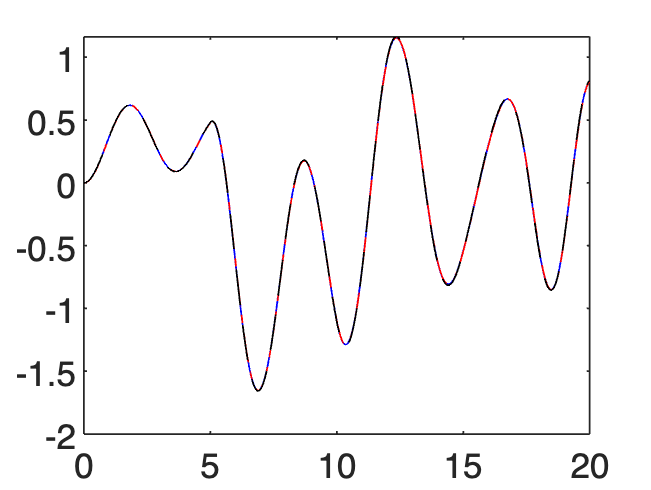

tt1 = 0:0.01:5-0.01;
f1 = 1/5;
tri_wave1 = 2 * abs( 2 * (tt1*f1 - floor(tt1*f1 + 0.5)) ) - 1;
tt2 = 0:0.01:5-0.01;
f2 = 1/2.5;
tri_wave2 = 2 * abs( 2 * (tt2*f2 - floor(tt2*f2 + 0.5)) ) - 1;
t = 0:0.01:20-0.01; 
u = [ones(1,5/0.01)';-2*ones(1,5/0.01)';tri_wave1';tri_wave2'];
msd_c_out = lsim(msd_c,u,t);
msd_d_out = lsim(msd_d,u,t);
estimate_msd_out = lsim(estimated_msd,u,t);
figure;
plot(t,msd_d_out,'b',t,msd_c_out,'r-.',t,estimate_msd_out,'k--');

autotune PID controller

autotune_pid = pid(20.6111265111836,14.9319590012965,7.11257203463944, 1/100, 0.01);
autotune_L = series(autotune_pid, msd_d);
autotune_F = feedback(autotune_L, 1);

estimated PID using forward model tested on real msd and on estimated msd

estimated_pid = pid(16.8,18.5,7.9, 1/100,0.01);
estimated_L = series(estimated_pid, msd_d);
estimated_F = feedback(estimated_L, 1);
estimated_L_estimated = series(estimated_pid, estimated_msd);
estimated_F_estimated = feedback(estimated_L_estimated, 1);

Simulation of sistemwith PID

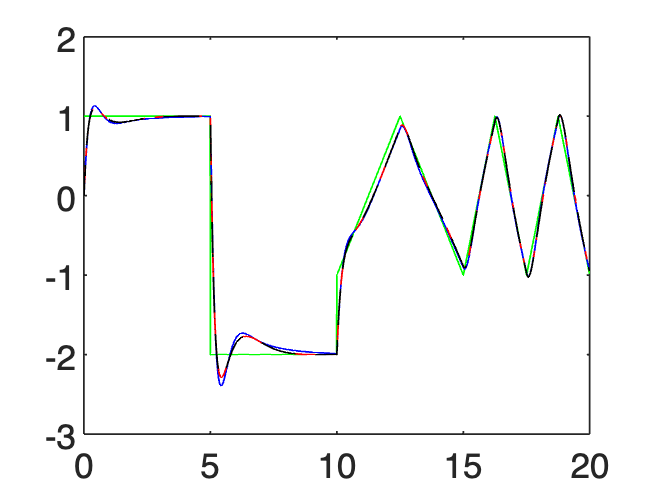

autotune_pid_msd_d_out = lsim(autotune_F,u,t);
estimated_pid_msd_d_out = lsim(estimated_F,u,t);
estimated_pid_estimate_msd_out = lsim(estimated_F_estimated,u,t);
plot(t,u,'g',t,autotune_pid_msd_d_out,'b',t,estimated_pid_msd_d_out,'r-.',t,estimated_pid_estimate_msd_out,'k--');

Save data on file

T = table(t(:), u(:), autotune_pid_msd_d_out(:), estimated_pid_estimate_msd_out(:),estimated_pid_msd_d_out(:), 'VariableNames', {'Time', 'target', 'autotune', 'est_est', 'estimate'});
writetable(T, 'PID_test.csv');